# Práctica N°4 Control Biológico.

Autor: Tomás Vidal

### Notas

-

## Preguntas

- ¿Qué hacer cuando no deja simular 30 horas? (error de step)

## Proceso de respiración de *S. cerevisiae *con sistema de cultivo fed-batch


$$\[
\begin{cases} 
\dot{x} = \mu x - Dx \\ 
\dot{s} = -k\mu x + D(s_{in}-s) \\ 
\dot{V} = F_{in}
\end{cases}
\]$$



$$\[
\mu(s) = \mu_{\max} \frac{s}{s + K_s}
\]$$


DatosModeloTP4

sim_hours = 30; % la cantidad de horas que se van a simular
timeStep = 2e-2;

% Configuración de la simulación de Simulink
simConfig.StopTime = num2str(sim_hours);
simConfig.Solver = 'ode1';
simConfig.FixedStep = num2str(timeStep);

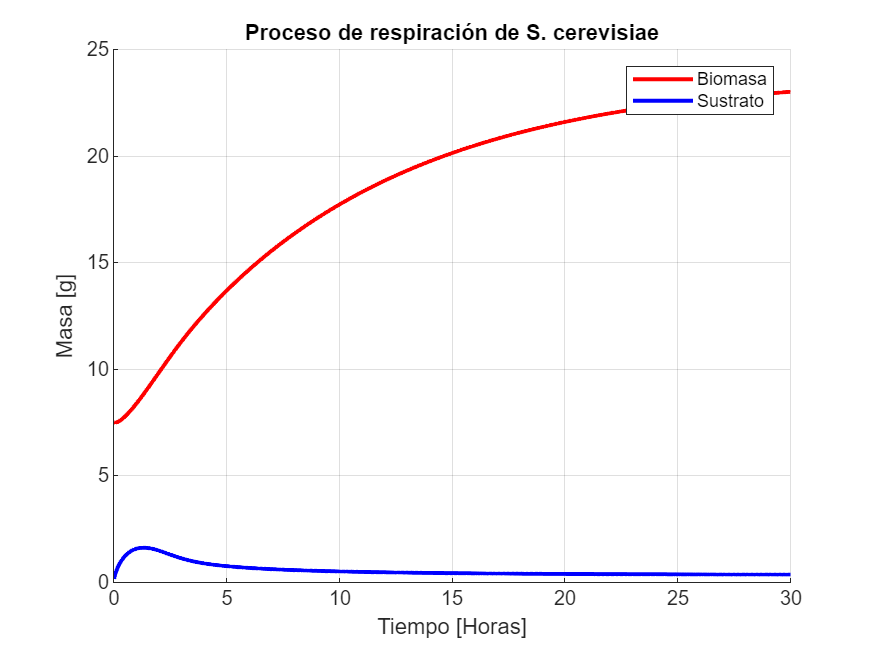

D=0.1;
params={1};
for i=1:length(params)

    sim_out = sim('TP4', simConfig);
    
    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrate = reshape(states(:,2), size(time));
    mu = sim_out.mu_s.Data;
    
end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Proceso de respiración de S. cerevisiae');
xlabel('Tiempo [Horas]');
ylabel('Masa [g]');
plot(time, biomass, 'r', 'LineWidth', 2);
plot(time, sustrate, 'b', 'LineWidth', 2);
legend('Biomasa', 'Sustrato');

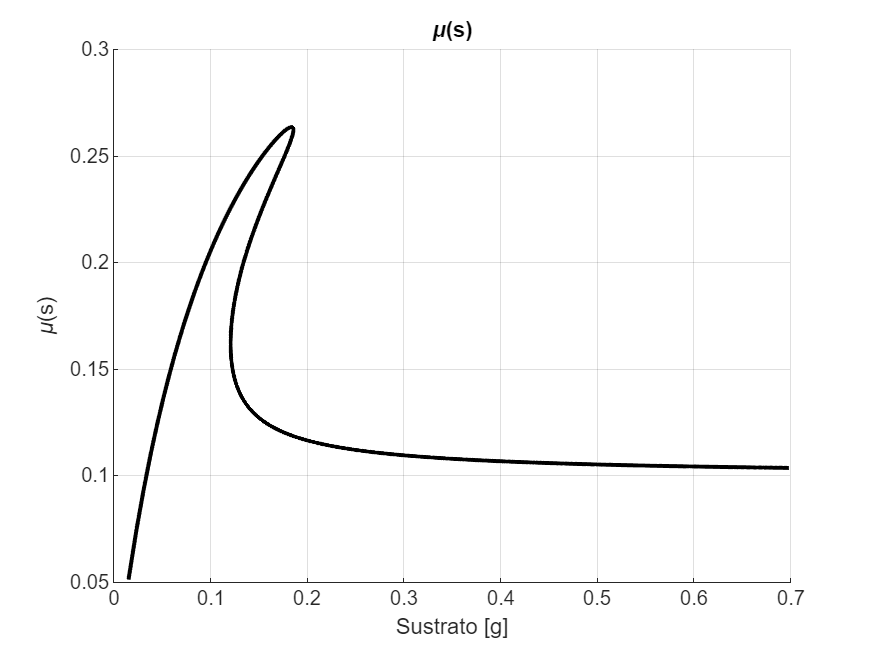


fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('\mu(s)');
xlabel('Sustrato [g]');
ylabel('\mu(s)');
plot(sustrate.*volume, mu, 'k', 'LineWidth', 2);

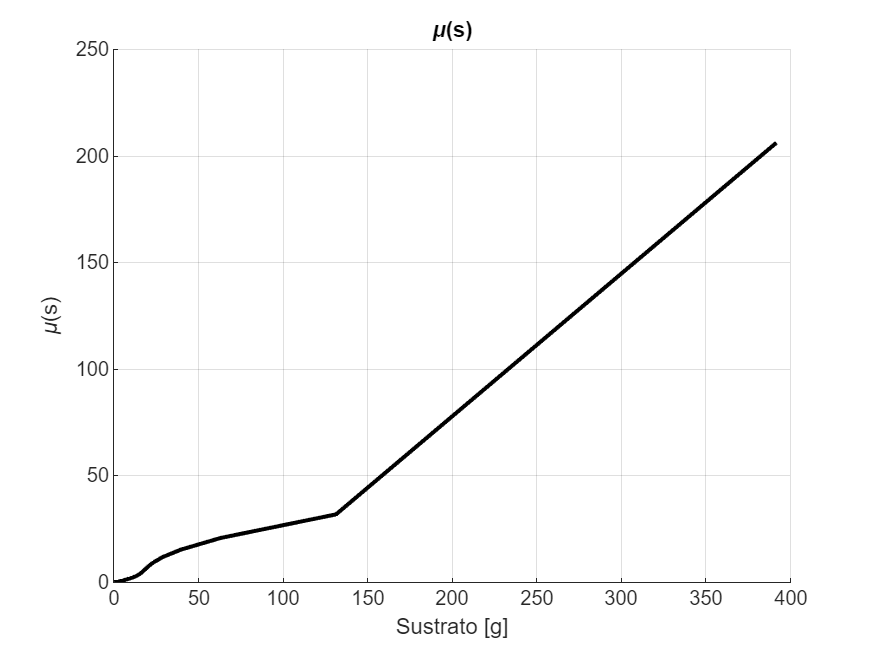


[mu_freq1] = abs(fft(mu));
[s_freq1] = abs(fft(sustrate.*volume));

% Comportamiento en frecuencia de mu
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('\mu(s)');
xlabel('Sustrato [g]');
ylabel('\mu(s)');
plot(s_freq1, mu_freq1, 'k', 'LineWidth', 2);


% Comportamiento en frecuencia del sustrato
Fs = 1 / timeStep;
L = length(sustrate);
Y = fft(sustrate);

P2 = abs(Y / L);
P1 = P2(1:L/2+1);

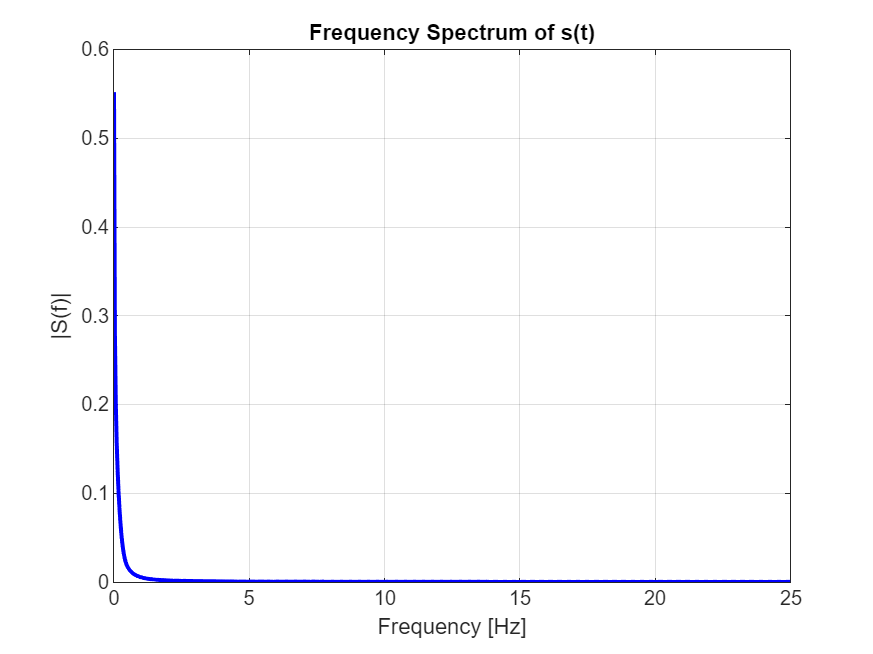

P1(2:end-1) = 2*P1(2:end-1);

f = Fs * (0:(L/2)) / L;

fig = figure();
set(fig, 'Position', [0 0 800 600]);
plot(f, P1, 'b', 'LineWidth', 2);
title('Frequency Spectrum of s(t)');
xlabel('Frequency [Hz]');
ylabel('|S(f)|');
grid on;

Ahora trato de implementar una ley de alimentación exponencial

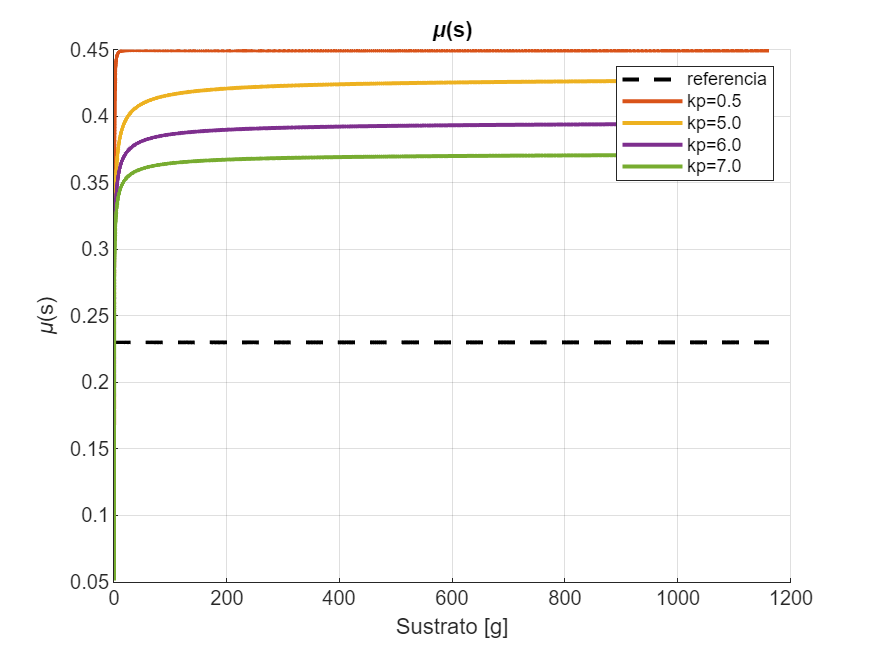

mu_r=0.23; % mu de referencia a operar

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = 0.1259;
modelParameters.mu_r=mu_r;
% modelParameters.kp=0.1; % factor proporcional

params={0.5,5,6,7};
mus=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)

    % fprintf("kp=%.1f\n", params{i});
    modelParameters.kp=params{i};

    sim_out = sim('TP4_control', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrate = reshape(states(:,2), size(time)).*volume;
    Do = sim_out.Do.Data;
    mus{i} = sim_out.mu_s.Data;

    mu_r_vector = ones(1, length(mus{i}))*mu_r;
    
    error{i}=(mu_r_vector-mus{i});
    MSE{i} = immse(reshape(mu_r_vector, size(mus{i})), mus{i});

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('\mu(s)');
xlabel('Sustrato [g]');
ylabel('\mu(s)');
plot(sustrate, mu_r_vector, 'k--', 'LineWidth', 2);
plot(sustrate, mus{1}, 'LineWidth', 2);
plot(sustrate, mus{2}, 'LineWidth', 2);
plot(sustrate, mus{3}, 'LineWidth', 2);
plot(sustrate, mus{4}, 'LineWidth', 2);

legend('referencia' ...
    ,sprintf('kp=%.1f', params{1}), ...
    sprintf('kp=%.1f', params{2}), ...
    sprintf('kp=%.1f', params{3}), ...
    sprintf('kp=%.1f', params{4}));

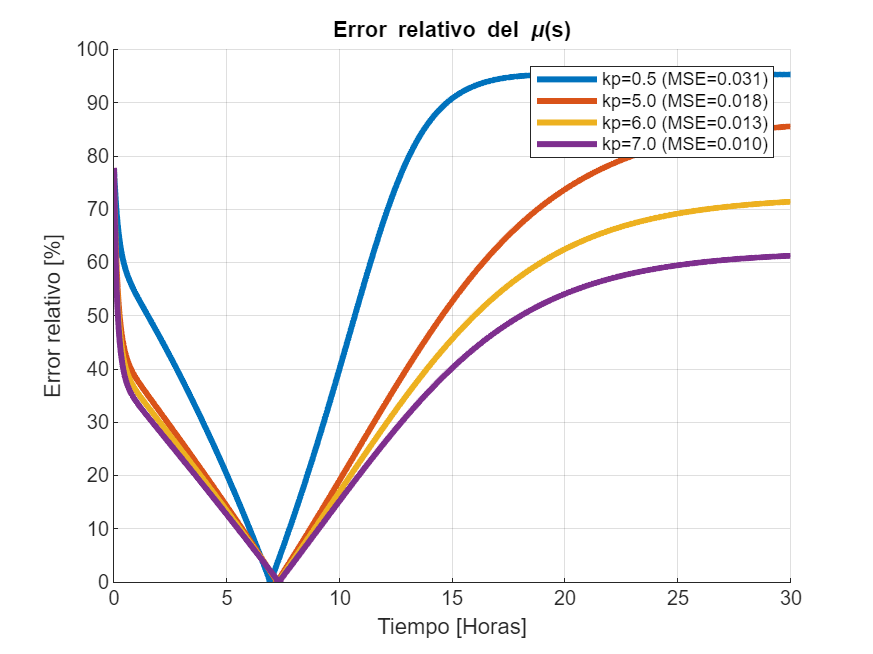


% fig = figure();
% set(fig,'Position',[0 0 800 600]);
% hold on; grid on;
% title('Acción de control u(t) (Dilución)');
% xlabel('Tiempo [Horas]');
% ylabel('Dilución (t)');
% plot(time, Do, 'LineWidth', 2);

% Error relativo
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo del \mu(s)');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{2}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{3}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{4}), mu_r_vector), 'LineWidth', 3);

legend(sprintf('kp=%.1f (MSE=%.3f)', params{1}, MSE{1}), ...
    sprintf('kp=%.1f (MSE=%.3f)', params{2}, MSE{2}), ...
    sprintf('kp=%.1f (MSE=%.3f)', params{3}, MSE{3}), ...
    sprintf('kp=%.1f (MSE=%.3f)', params{4}, MSE{4}));

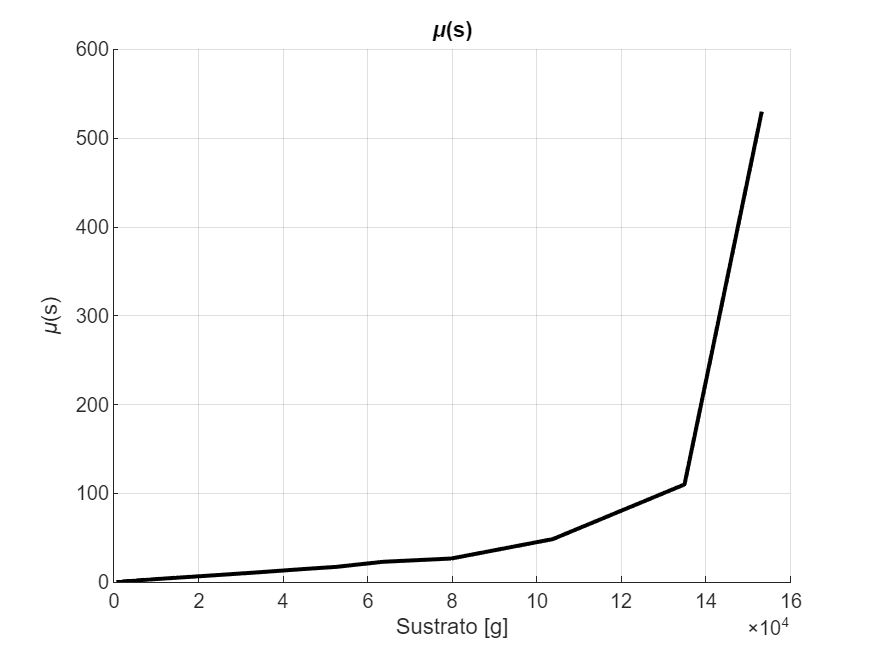


[mu_freq2] = abs(fft(mus{1}));
[s_freq2] = abs(fft(sustrate));

% Comportamiento en frecuencia de mu
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('\mu(s)');
xlabel('Sustrato [g]');
ylabel('\mu(s)');
plot(s_freq2, mu_freq2, 'k', 'LineWidth', 2);

Ahora agrego un término integrativo

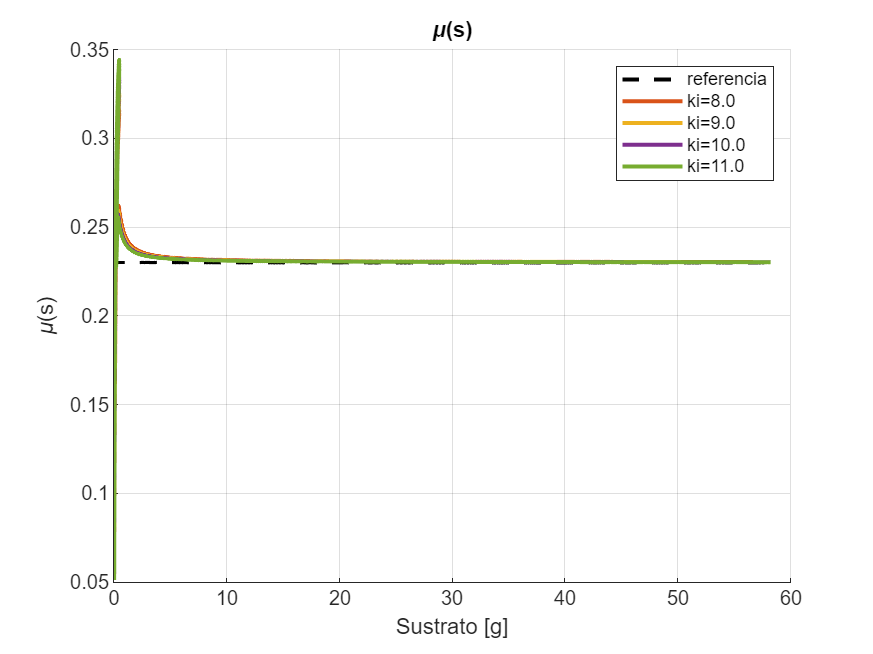

mu_r=0.23; % mu de referencia a operar

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = 0.1259;
modelParameters.mu_r=mu_r;
modelParameters.kp=0.05; % factor proporcional
% modelParameters.ki=0.1; % factor integrativa
e0=mu_r*1.5;

params={8, 9, 10, 11};
mus=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)

    % fprintf("kp=%.1f\n", params{i});
    modelParameters.ki=params{i};

    sim_out = sim('TP4_control2', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrate = reshape(states(:,2), size(time)).*volume;
    Do = sim_out.Do.Data;
    mus{i} = sim_out.mu_s.Data;

    mu_r_vector = ones(1, length(mus{i}))*mu_r;
    
    error{i}=(mu_r_vector-mus{i});
    MSE{i} = immse(reshape(mu_r_vector, size(mus{i})), mus{i});

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('\mu(s)');
xlabel('Sustrato [g]');
ylabel('\mu(s)');
plot(sustrate, mu_r_vector, 'k--', 'LineWidth', 2);
plot(sustrate, mus{1}, 'LineWidth', 2);
plot(sustrate, mus{2}, 'LineWidth', 2);
plot(sustrate, mus{3}, 'LineWidth', 2);
plot(sustrate, mus{4}, 'LineWidth', 2);

legend('referencia' ...
    ,sprintf('ki=%.1f', params{1}), ...
    sprintf('ki=%.1f', params{2}), ...
    sprintf('ki=%.1f', params{3}), ...
    sprintf('ki=%.1f', params{4}));

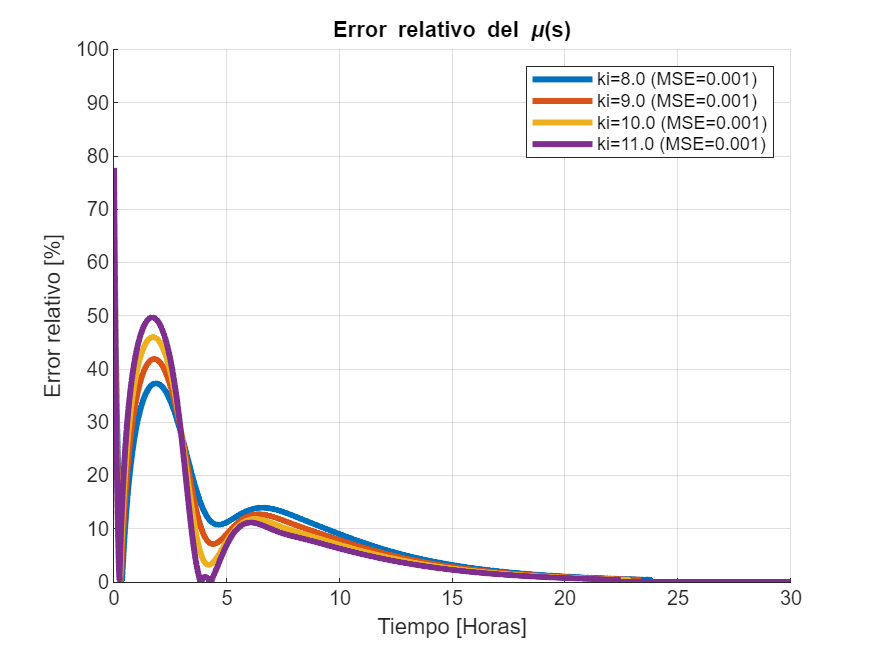


% Error relativo
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo del \mu(s)');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{2}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{3}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{4}), mu_r_vector), 'LineWidth', 3);

legend(sprintf('ki=%.1f (MSE=%.3f)', params{1}, MSE{1}), ...
    sprintf('ki=%.1f (MSE=%.3f)', params{2}, MSE{2}), ...
    sprintf('ki=%.1f (MSE=%.3f)', params{3}, MSE{3}), ...
    sprintf('ki=%.1f (MSE=%.3f)', params{4}, MSE{4}));

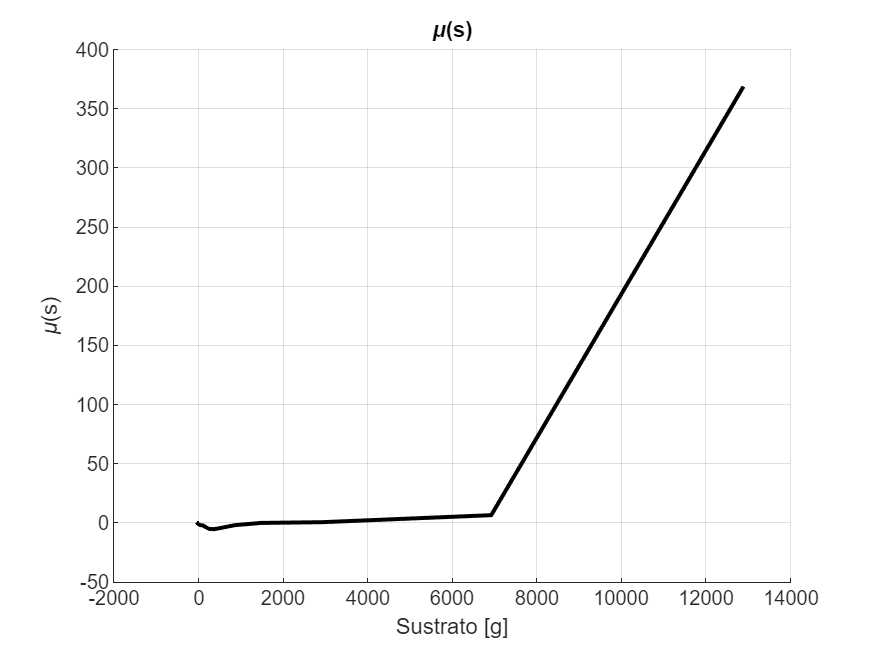


[mu_freq3] = abs(fft(mus{1}));
[mu_freq32] = abs(fft(mus{2}));
[mu_freq33] = abs(fft(mus{3}));
[s_freq3] = abs(fft(sustrate));

% Comportamiento en frecuencia de mu
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('\mu(s)');
xlabel('Sustrato [g]');
ylabel('\mu(s)');
plot(s_freq, mu_freq, 'k', 'LineWidth', 2);

Comportamiento en frecuencia de lo anterior

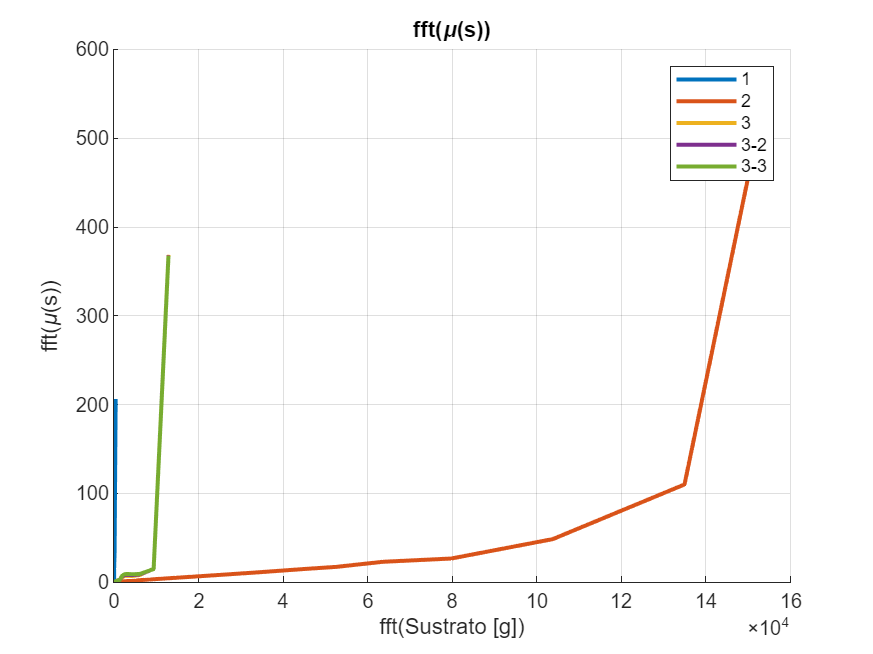

% Comportamiento en frecuencia de mu
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('fft(\mu(s))');
xlabel('fft(Sustrato [g])');
ylabel('fft(\mu(s))');
plot(s_freq1, mu_freq1, 'LineWidth', 2);
plot(s_freq2, mu_freq2, 'LineWidth', 2);
plot(s_freq3, mu_freq3, 'LineWidth', 2);
plot(s_freq3, mu_freq32, 'LineWidth', 2);
plot(s_freq3, mu_freq33, 'LineWidth', 2);

legend('1', '2', '3', '3-2', '3-3');